clear
conv = [pi/180, pi/180, 1];

Group = load('Original groups\GT_Vol_1_Slice_1_5.mat');
Group = Group.Group;
True_pos = cellfun(@(x) x(:, 2:4), Group, 'UniformOutput', false);
True_pos = cellfun(@(x) round(x(:, 1:3).*conv*(10^8))/(10^8), True_pos, 'UniformOutput', false);

% Collecting galaxies from Eke_fof into EGs
Eke_fof = load("FOF_Eke\Fof_All_vol_1_slice_1_5.mat");
EG_eke = Eke_fof.G_FOF;
EG_eke_pos = EG_eke;
EG_eke_pos = cellfun(@(x) round(x(:, 1:3).*conv*(10^8))/(10^8), EG_eke_pos, 'UniformOutput', false);

% Collecting galaxies from Gama_fof into EGs
Gama_fof = load("Gama_FOF\GAMAFOF_All_vol_1_slice_1_5.mat");
Gama_fof = Gama_fof.G_FOF;
Gama_fof_pos = cellfun(@(x) x(:, 2:4), Gama_fof, 'UniformOutput', false);
Gama_fof_pos = cellfun(@(x) round(x(:, 1:3).*conv*(10^8))/(10^8), Gama_fof_pos, 'UniformOutput', false);
% Gama_fof -> Cell of EGs

% Collecting galaxies from Hough into EGs
Hough = load("Hough2\G_V_paperAll_Vol_1_S_1.mat");
Hough_pos = Hough.New_set;
Hough_mass = Hough.mass_no_final;
Hough_grpid = Hough.Group_Index;
Hough_pos = cellfun(@(x) round(x(:, 1:3).*conv*(10^8))/(10^8), Hough_pos, 'UniformOutput', false);

load("Linked_TG_and_EG.mat")

## Precision Calculation

TG_mmg = cell2mat(table2array(TG_link(:, 4)));

% Eke FOF
TG_to_eke = cell2mat(table2array(TG_link(:, "eke")));
eke_primary = zeros(length(EG_eke), 1);

for k = 1:length(EG_eke)
    eke_assoc = find(TG_to_eke == k);
    if ~isempty(eke_assoc)
        masses = TG_mmg(eke_assoc);
        eke_primary(k) = eke_assoc(masses == max(masses));
    end
end
mapped_EG_eke = find(eke_primary ~= 0);
precision_eke = length(mapped_EG_eke) / length(eke_primary)

precision_eke = 0


% Gama FOF
TG_to_gama = cell2mat(table2array(TG_link(:, "gama")));
gama_primary = zeros(length(Gama_fof), 1);

for k = 1:length(Gama_fof)
    gama_assoc = find(TG_to_gama == k);
    if ~isempty(gama_assoc)
        masses = TG_mmg(gama_assoc);
        gama_primary(k) = gama_assoc(masses == max(masses));
    end
end
mapped_EG_gama = find(gama_primary ~= 0);
precision_gama = length(mapped_EG_gama) / length(gama_primary)

precision_gama = 0.5306


% Hough
TG_to_hough = cell2mat(table2array(TG_link(:, "hough")));
hough_primary = zeros(length(Hough_pos), 1);

for k = 1:length(Hough_grpid)
    hough_assoc = find(TG_to_hough == k);
    if ~isempty(hough_assoc)
        masses = TG_mmg(hough_assoc);
        hough_primary(k) = hough_assoc(masses == max(masses));
    end
end
mapped_EG_hough = find(hough_primary ~= 0);
precision_hough= length(mapped_EG_hough) / length(hough_primary)

precision_hough = 0.5670


save("Associated_Groups.mat", "mapped_EG_hough", "mapped_EG_gama", "mapped_EG_eke");

## Recall Calculation

% First method
% Eke FOF
detected_Eke = find(TG_to_eke ~= 0);
recall_eke = length(detected_Eke) / length(Group)

recall_eke = 0


% Gama fof
detected_gama = find(TG_to_gama ~= 0);
recall_gama = length(detected_gama) / length(Group)

recall_gama = 0.7794


% Hough 
detected_hough = find(TG_to_hough ~= 0);
recall_hough = length(detected_hough) / length(Group)

recall_hough = 0.9706

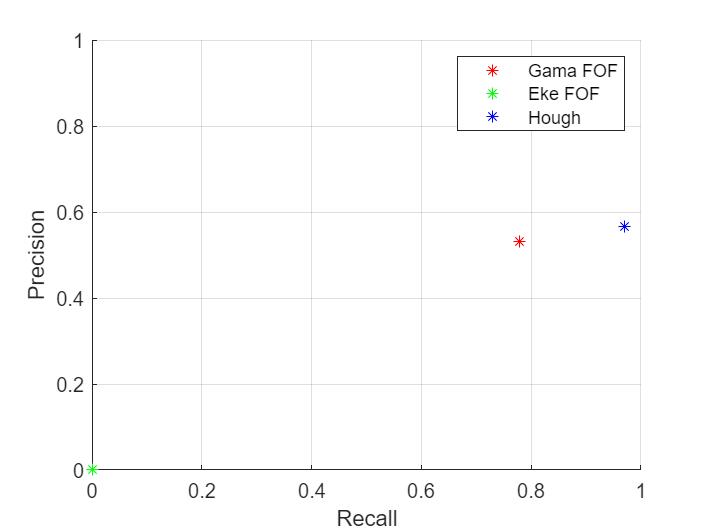


scatter(recall_gama, precision_gama, 'r*')
hold on;
scatter(recall_eke, precision_eke, 'g*')
hold on;
scatter(recall_hough, precision_hough, 'b*')
xlim([0, 1])
ylim([0, 1])
grid on;
legend(['Gama FOF', "Eke FOF", 'Hough'])
xlabel("Recall")
ylabel("Precision")
hold off;


% Second method
% Eke fof
recall_hough = length(unique(mapped_EG_hough)) / length(Group)

recall_hough = 0.8088

recall_eke = length(unique(mapped_EG_eke)) / length(Group)

recall_eke = 0

recall_gama = length(unique(mapped_EG_gama)) / length(Group)

recall_gama = 0.7647

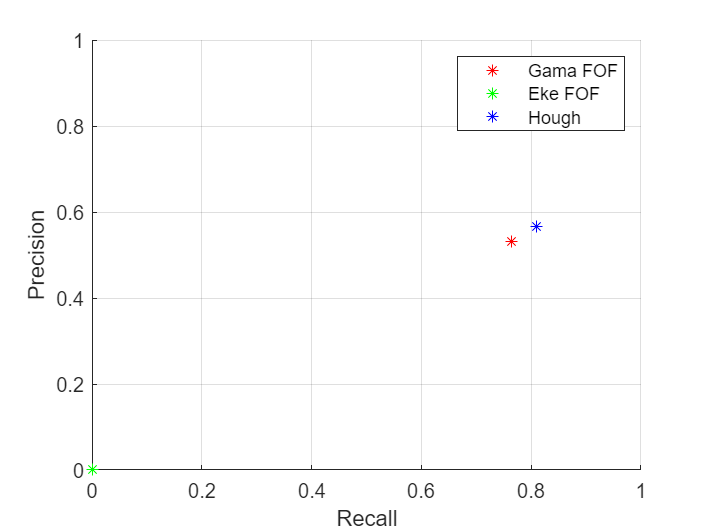


scatter(recall_gama, precision_gama, 'r*')
hold on;
scatter(recall_eke, precision_eke, 'g*')
hold on;
scatter(recall_hough, precision_hough, 'b*')
xlim([0, 1])
ylim([0, 1])
grid on;
legend(['Gama FOF', "Eke FOF", 'Hough'])
xlabel("Recall")
ylabel("Precision")
hold off;